clc; clear; close all;

% Directory containing .h5 files
input_dir = 'C:\Users\andre\Year5\EE581\Project\archive\TrainData\img'; % Change this to your directory

% Get list of .h5 files
h5Files = dir(fullfile(input_dir, '*.h5'))

h5Files = 3799×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


img_path = 'C:\Users\andre\Year5\EE581\Project\archive\TrainData\img\image_1.h5'

img_info = struct with fields:
      Filename: 'C:\Users\andre\Year5\EE581\Project\archive\TrainData\img\image_1.h5'
          Name: '/'
        Groups: []
      Datasets: [1×1 struct]
     Datatypes: []
         Links: []
    Attributes: []


img_name = 'img'

img_chs = img_chs(:,:,1) =

    1.1837    1.1837    1.1837    1.1890    1.1890    1.2205    1.2205    1.2214    1.2214    1.2214    1.2214    1.1846    1.1846    1.1846    1.1837    1.1837    1.1846    1.1819    1.1819    1.1765    1.1765    1.1765    1.1657    1.1657    1.1657    1.1621    1.1621    1.1621    1.1603    1.1603    1.1603    1.1612    1.1612    1.1612    1.1612    1.1630    1.1630    1.1630    1.1612    1.1612    1.1612    1.1612    1.1612    1.1612    1.1612    1.1612    1.1612    1.1774    1.1774    1.1846    1.1846    1.1846    1.1756    1.1756    1.1711    1.1711    1.1711    1.1396    1.1396    1.1396    1.1378    1.1378    1.1378    1.1180    1.1180    1.1180    1.1180    1.1180    1.1180    1.1180    1.1126    1.1126    1.1126    1.1126    1.1126    1.1135    1.1135    1.1135    1.1135    1.1126    1.1126    1.1126    1.1189    1.1189    1.1189    1.1198    1.1198    1.1315    1.1315    1.1315    1.1315    1.1315    1.1378    1.1378    1.1378    1.1378    1.1378  

rgb_img = rgb_img(:,:,1) =

    1.5320    1.5634    1.5387    1.5522    1.4758    1.4197    1.4219    1.3905    1.3905    1.3545    1.3500    1.5387    1.6510    1.5994    1.4601    1.4107    1.2804    1.1883    1.1861    1.2490    1.2894    1.2512    1.3770    1.3658    1.3658    1.3321    1.3253    1.3163    1.2894    1.2871    1.2445    1.2085    1.1950    1.1793    1.1569    1.1861    1.2085    1.2063    1.2377    1.2602    1.2422    1.2849    1.2849    1.3253    1.3253    1.3500    1.3208    1.2759    1.3478    1.3208    1.3208    1.3882    1.2849    1.2332    1.3523    1.4960    1.5140    1.4152    1.4242    1.4107    1.3905    1.3792    1.3792    1.4084    1.4579    1.4668    1.4511    1.5275    1.5724    1.5792    1.7409    1.6892    1.7544    1.6645    2.0262    2.1430    2.1430    1.9251    1.9251    1.9049    2.5720    3.0011    3.7311    1.8487    1.7342    1.5118    1.4803    1.4848    1.4826    1.4354    1.3815    1.4039    1.4107    1.4084    1.4803    1.4803    1.6084  

ans =    128   128     3


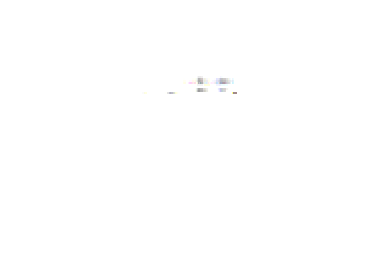

for i = 1%:length(h5Files)
    % Full path to the .h5 file
    img_path = fullfile(input_dir, h5Files(i).name)
    
    % Read the HDF5 dataset 
    img_info = h5info(img_path)
    img_name = img_info.Datasets(i).Name
    img_chs = h5read(img_path, ['/' img_name])
    
    % Extract channels
    R_CH = squeeze(img_chs(4,:,:));
    G_CH = squeeze(img_chs(3,:,:));
    B_CH = squeeze(img_chs(2,:,:));
    
    % Combine into an RGB image
    rgb_img = double(cat(3, R_CH, G_CH, B_CH))
    size(rgb_img)

    figure;
    imshow(rgb_img);

    % Normalize images
    if max(rgb_img(:)) > 1
        rgb_img = rgb_img / max(rgb_img(:)); % Scale to [0, 1]
    end
    figure;
    imshow(rgb_img);
            % if max(label(:)) > 1
            %     label = label / max(label(:)); % Scale to [0, 1]
            % end

    % % Normalize if needed (convert to uint8 if data is not in 0-255 range)
    % if max(rgb_img(:)) > 1
    %     rgb_img = uint8(rgb_img);
    % else
    %     rgb_img = uint8(rgb_img * 255);
    % end

    figure;
    imshow(rgb_img);
end

    % Normalize if needed (convert to uint8 if data is not in 0-255 range)
    if max(rgb_img(:)) > 1
        rgb_img = uint8(rgb_img);
    else
        rgb_img = uint8(rgb_img * 255);
    end
    

data = 'C:/Users/andre/EE581-LandlideProj/data/archive/TrainData/';


img_chs = data+"img/image_1.h5";
lbl = data+"mask/mask_1.h5";
img_chs = h5read(img_chs,"/img")
img_slope = 1 - img_chs(:,:,12);
size(img_slope)
lbl = 1 - h5read(lbl,"/mask");
figure;
imshow(img_slope);
title("Img Slope");
figure;
imshow(lbl);
title("Mask");